`In the name of God`

# Blind Source Separation

# Homework #14

**Ashkan Jafari**

**810197483**

**NOTE:**

**In this project I have struggled with the initial separation marix problem and at the end I ran my code several times with a random initial separation matrix and chose the best random initial separation matrix.**

Loading.

load('hw14.mat');

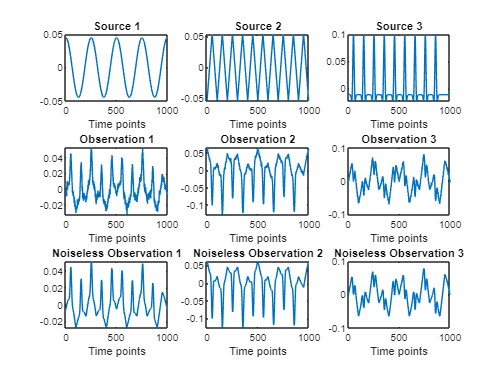

X_noiseless = A*S;
X = X_noiseless + Noise;
time_points = 1:length(S(1,:));


figure
subplot(3,3,1)
plot(time_points,S(1,:))
title('Source 1')
xlabel('Time points')

subplot(3,3,2)
plot(time_points,S(2,:))
title('Source 2')
xlabel('Time points')

subplot(3,3,3)
plot(time_points,S(3,:))
title('Source 3')
xlabel('Time points')

subplot(3,3,4)
plot(time_points,X(1,:))
title('Observation 1')
xlabel('Time points')

subplot(3,3,5)
plot(time_points,X(2,:))
title('Observation 2')
xlabel('Time points')


subplot(3,3,6)
plot(time_points,X(3,:))
title('Observation 3')
xlabel('Time points')


subplot(3,3,7)
plot(time_points,X_noiseless(1,:))
title('Noiseless Observation 1')
xlabel('Time points')


subplot(3,3,8)
plot(time_points,X_noiseless(2,:))
title('Noiseless Observation 2')
xlabel('Time points')


subplot(3,3,9)
plot(time_points,X_noiseless(3,:))
title('Noiseless Observation 3')
xlabel('Time points')

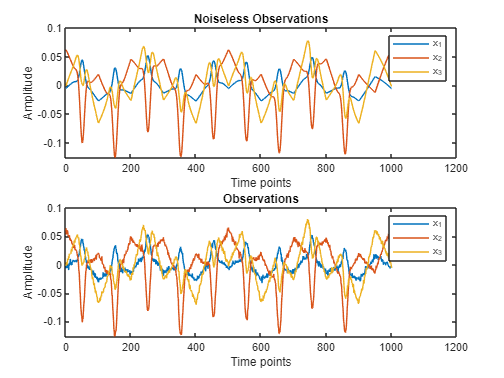

figure
subplot(2,1,1)
plot(time_points,X_noiseless(1,:),time_points,X_noiseless(2,:),time_points,X_noiseless(3,:))
title('Noiseless Observations')
xlabel('Time points')
ylabel('Amplitude')
legend('x_1','x_2','x_3')

subplot(2,1,2)
plot(time_points,X(1,:),time_points,X(2,:),time_points,X(3,:))
title('Observations')
xlabel('Time points')
ylabel('Amplitude')
legend('x_1','x_2','x_3')

## ICA - Making the Observations Independent

$f\left(B\right)=D_{\mathrm{KL}} \left(P_Y \left(Y\right)\left|\right|\prod_{m=1}^M P_{y_m } \left(y_m \right)\right)$,$\hat{B} =\mathrm{argmin}\;f\left(B\right)\;\;\;s\ldotp t\;\;\;b_i^T b_i =1$

### Parallel ICA


$$f\left(B\right)=\sum_{m=1}^M H\left(y_m \right)-H\left(Y\right)$$


iters = 1000;
err = 1e-8;
mu = 0.02;

init_B = [3.1,0.94,-0.19;-0.8,-0.92,0.94;2.05,0.01,-0.68];
init_B = normr(init_B);
tic
[B, e] = g_projection(X,init_B,mu,iters,err);
toc

Elapsed time is 2.820706 seconds.


**The time of convergence is about 2.8 seconds.**

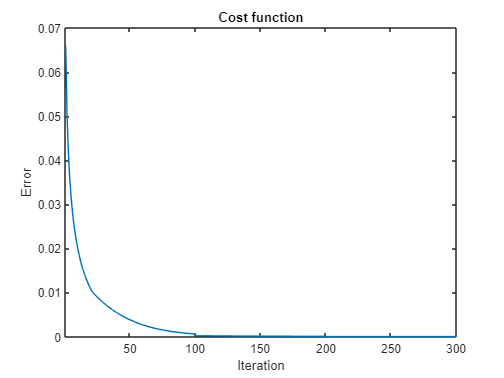

figure
plot(e)
title('Cost function')
xlabel('Iteration')
xlim([1,300])
ylabel('Error')

MixtureMatrix_Multiplied_SeparationMatrix = A*B

MixtureMatrix_Multiplied_SeparationMatrix =     0.3556   -0.2137    0.2041
   -0.1151    1.0536    0.2692
    0.1454    0.0982    1.2372


**As it is shown above the multiplication of Mixture Matrix and Separation Matrix is close to Permutation Matrix.**

S_hat = B*X;

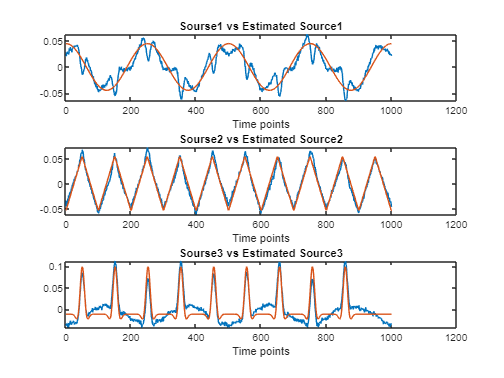

figure
subplot(3,1,1)
plot(time_points,S_hat(1,:),time_points,S(1,:))
title('Sourse1 vs Estimated Source1')
xlabel('Time points')

subplot(3,1,2)
plot(time_points,S_hat(2,:),time_points,S(2,:))
title('Sourse2 vs Estimated Source2')
xlabel('Time points')

subplot(3,1,3)
plot(time_points,S_hat(3,:),time_points,S(3,:))
title('Sourse3 vs Estimated Source3')
xlabel('Time points')

Errr = (norm(S_hat - S,"fro")/norm(S,"fro"))^2

Errr = 0.1619

**The error of the final result is shown above.**

### Deflation ICA


$$f\left(B\right)=\sum_{m=1}^M H\left(y_m \right)$$


[Z,W] = whiten(X);

init_B = [0.9 0.1 0.67; 0.95 0.84 0.75; 0.65 0.93 0.74];
init_B = normr(init_B);

iters = 1000;
err = 1e-7;
mu = 0.02;
tic
[B, e] = deflation_g_projection(Z,init_B,mu,iters,err);
toc

Elapsed time is 0.032020 seconds.


**The time of convergence is about 0.03 seconds.**

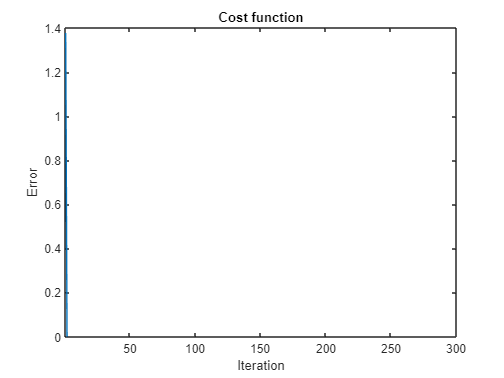

figure
plot(e)
title('Cost function')
xlabel('Iteration')
xlim([1,300])
ylabel('Error')

MixtureMatrix_Multiplied_SeparationMatrix = (B*W)*A

MixtureMatrix_Multiplied_SeparationMatrix =     0.7591   -0.5938   -0.0545
    0.6255    0.8633   -0.1851
    0.1184   -0.4868    1.1251


**As it is shown above the multiplication of Mixture Matrix and Separation Matrix is close to Permutation Matrix.**

S_hat = B*Z;

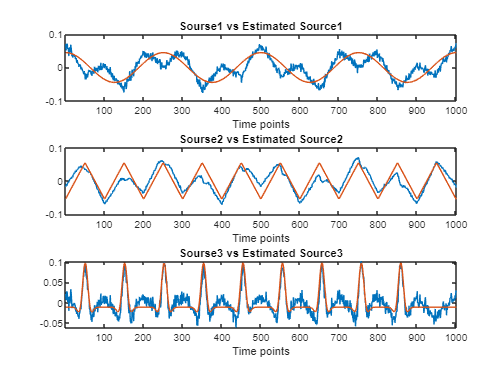

figure
subplot(3,1,1)
plot(time_points,S_hat(1,:),time_points,S(1,:))
title('Sourse1 vs Estimated Source1')
xlabel('Time points')
xlim([1,1001])

subplot(3,1,2)
plot(time_points,S_hat(2,:),time_points,S(2,:))
title('Sourse2 vs Estimated Source2')
xlabel('Time points')
xlim([1,1001])

subplot(3,1,3)
plot(time_points,S_hat(3,:),time_points,S(3,:))
title('Sourse3 vs Estimated Source3')
xlabel('Time points')
xlim([1,1001])

Errr = (norm(S_hat - S,"fro")/norm(S,"fro"))^2

Errr = 0.4203

**The error of the final result is shown above.**

### Equivarient

iters = 2000;
err = 1e-8;
mu = 0.2;

init_B = [0.9 0.1 0.67; 0.95 0.84 0.75; 0.65 0.93 0.74];
init_B = normr(init_B);
tic
[B, e] = equivarient_g_projection(X,init_B,mu,iters,err);
toc

Elapsed time is 4.601283 seconds.


**The time of convergence is about 4.6 seconds.**

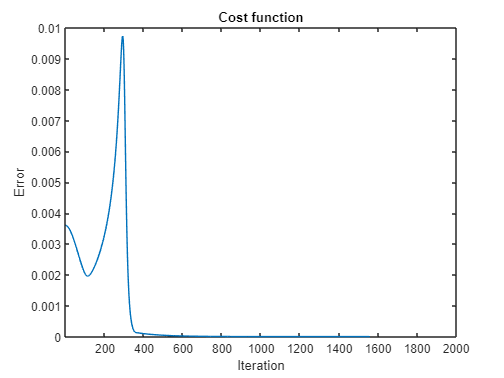

figure
plot(e)
title('Cost function')
xlabel('Iteration')
xlim([1,2000])
ylabel('Error')

MixtureMatrix_Multiplied_SeparationMatrix = B*A

MixtureMatrix_Multiplied_SeparationMatrix =     0.5111    0.8324    0.1279
    0.1091   -0.1895    0.2014
    0.9285    0.0685   -0.9240


**As it is shown above the multiplication of Mixture Matrix and Separation Matrix is close to Permutation Matrix.**

S_hat = B*X;

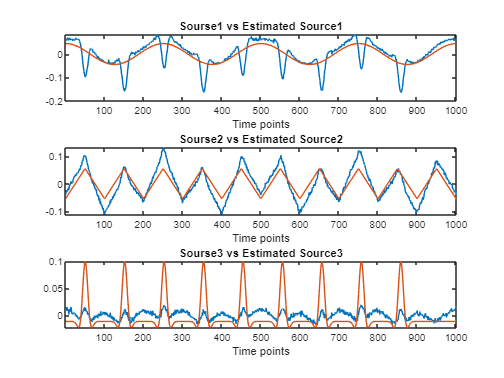

figure
subplot(3,1,1)
plot(time_points,1.3*S_hat(3,:),time_points,S(1,:))
title('Sourse1 vs Estimated Source1')
xlabel('Time points')
xlim([1,1001])

subplot(3,1,2)
plot(time_points,1.6*S_hat(1,:),time_points,S(2,:))
title('Sourse2 vs Estimated Source2')
xlabel('Time points')
xlim([1,1001])

subplot(3,1,3)
plot(time_points,S_hat(2,:),time_points,S(3,:))
title('Sourse3 vs Estimated Source3')
xlabel('Time points')
xlim([1,1001])

S_hat = [S_hat(3,:);S_hat(1,:);S_hat(2,:)]; 
Errr = (norm(S_hat - S,"fro")/norm(S,"fro"))^2

Errr = 0.6462

**The error of the final result is shown above.**

## **Conclusion**

As it is shown above the methods have results as below:

**Parallel ICA** : 2.8* second --> error = 0.16*

**Deflation ICA** :* 0.3 second --> error = 0.42*

**Equivarient** : 4* second --> error = 0.6*

These results show us that of **time** is our constraint then **Deflation ICA** is the better choise but if we need the most **accuracy** then **Parallel ICA** is the better choise.

It should be mentioned that in Deflation ICA, as the initial separation matrix has been choosen same as the converged separation matrix then evaluting the time-consumption of this method is not valid!

## ICA - Making the Observations Non-Gaussian

### Whitening

[Z,W] = whiten(X);
N = 3;

### Kurt Maximization (GP)

Row 1 of B

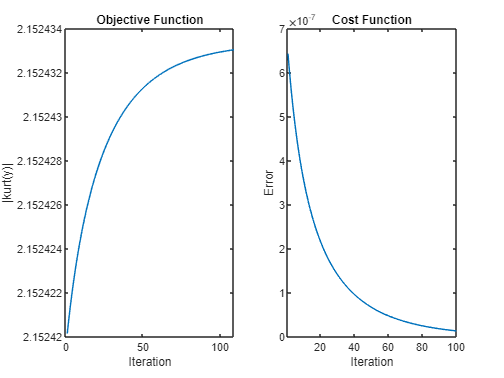

Row 2 of B

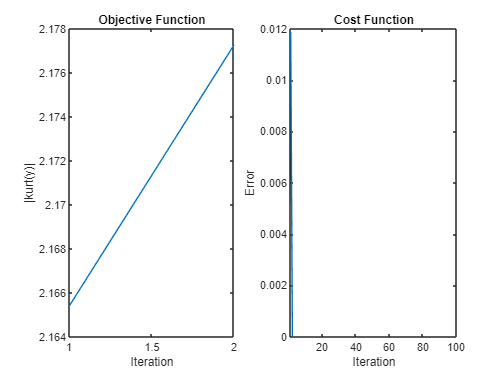

Row 3 of B

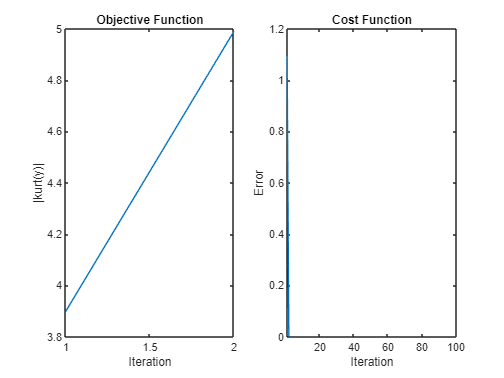

iters = 1000;
err = 1e-8;
mu = 0.2;
init_B = rand(N);
init_B = normr(init_B);
tic
B1 = Non_Gaussianing(Z,init_B,mu,iters,err,'GP',0);

toc

Elapsed time is 0.360341 seconds.


**The time of convergence is about 0.36 seconds.**

MixtureMatrix_Multiplied_SeparationMatrix = (B1*W)*A

MixtureMatrix_Multiplied_SeparationMatrix =     0.9038    0.2010    0.2653
   -0.0930    1.1321   -0.7272
    0.3949   -0.1131   -0.8389


**As it is shown above the multiplication of Mixture Matrix and Separation Matrix is close to Permutation Matrix.**

S_hat1 = B1*Z;
S_hat1 = S_hat1.*sqrt(Ex2(S,S)./Ex2(S_hat1,S_hat1));

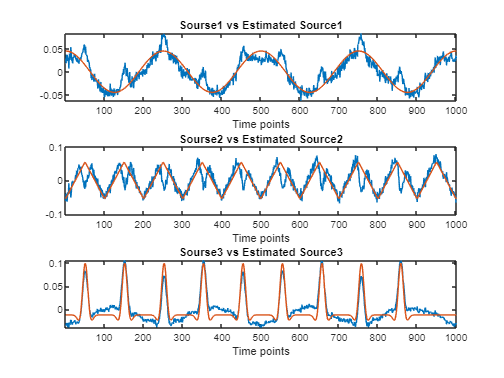

figure
subplot(3,1,1)
plot(time_points,S_hat1(1,:),time_points,S(1,:))
xlim([1,1001])
title('Sourse1 vs Estimated Source1')
xlabel('Time points')

subplot(3,1,2)
plot(time_points,S_hat1(2,:),time_points,S(2,:))
xlim([1,1001])
title('Sourse2 vs Estimated Source2')
xlabel('Time points')

subplot(3,1,3)
plot(time_points,-S_hat1(3,:),time_points,S(3,:))
xlim([1,1001])
title('Sourse3 vs Estimated Source3')
xlabel('Time points')

S_hat1 = [S_hat1(1,:);S_hat1(2,:);-S_hat1(3,:)]; 
Errr = (norm(S_hat1 - S,"fro")/norm(S,"fro"))^2

Errr = 0.3124

**The error of the final result is shown above.**

### Kurt Maximization (Fixed-Point)

Row 2 of B

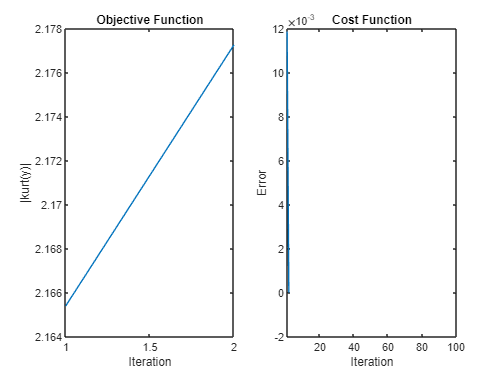

Row 3 of B

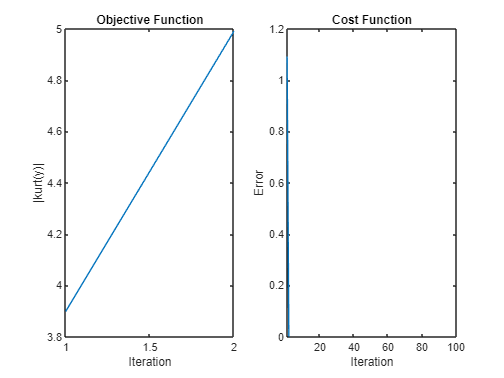

tic
B2 = Non_Gaussianing(Z,init_B,mu,iters,err,'FP',0);

toc

Elapsed time is 0.390716 seconds.


**The time of convergence is about 0.39 seconds.**

MixtureMatrix_Multiplied_SeparationMatrix = (B2*W)*A

MixtureMatrix_Multiplied_SeparationMatrix =    -0.9038   -0.2009   -0.2653
   -0.0930    1.1321   -0.7272
    0.3949   -0.1131   -0.8390


**As it is shown above the multiplication of Mixture Matrix and Separation Matrix is close to Permutation Matrix.**

S_hat2 = B2*Z;
S_hat2 = S_hat2.*sqrt(Ex2(S,S)./Ex2(S_hat2,S_hat2));

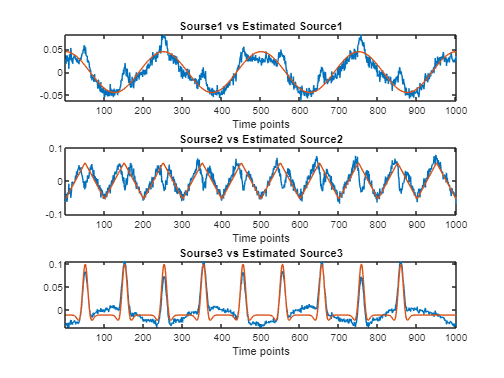

figure
subplot(3,1,1)
plot(time_points,-S_hat2(1,:),time_points,S(1,:))
xlim([1,1001])
title('Sourse1 vs Estimated Source1')
xlabel('Time points')

subplot(3,1,2)
plot(time_points,S_hat2(2,:),time_points,S(2,:))
xlim([1,1001])
title('Sourse2 vs Estimated Source2')
xlabel('Time points')

subplot(3,1,3)
plot(time_points,-S_hat2(3,:),time_points,S(3,:))
xlim([1,1001])
title('Sourse3 vs Estimated Source3')
xlabel('Time points')

S_hat2 = [-S_hat2(1,:);S_hat2(2,:);-S_hat2(3,:)]; 
Errr = (norm(S_hat2 - S,"fro")/norm(S,"fro"))^2

Errr = 0.3124

**The error of the final result is shown above.**

### Handle the Outlier Data (GP)

mu = 0.2;
tic
B3 = Non_Gaussianing(Z,init_B,mu,iters,err,'GP',1);
toc

Elapsed time is 0.556115 seconds.


**The time of convergence is about 0.55 seconds.**

MixtureMatrix_Multiplied_SeparationMatrix = (B3*W)*A

MixtureMatrix_Multiplied_SeparationMatrix =     0.9038    0.2009    0.2653
   -0.0930    1.1321   -0.7272
    0.3949   -0.1131   -0.8390


**As it is shown above the multiplication of Mixture Matrix and Separation Matrix is close to Permutation Matrix.**

S_hat3 = B3*Z;
S_hat3 = S_hat3.*sqrt(Ex2(S,S)./Ex2(S_hat3,S_hat3));

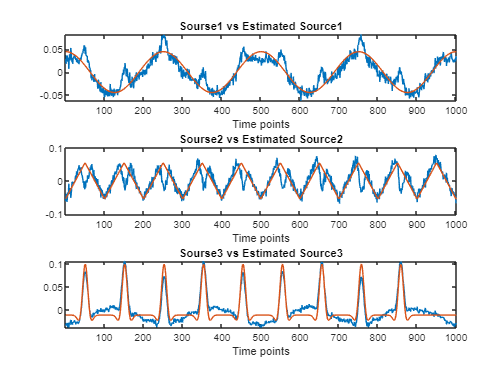

figure
subplot(3,1,1)
plot(time_points,S_hat3(1,:),time_points,S(1,:))
xlim([1,1001])
title('Sourse1 vs Estimated Source1')
xlabel('Time points')

subplot(3,1,2)
plot(time_points,S_hat3(2,:),time_points,S(2,:))
xlim([1,1001])
title('Sourse2 vs Estimated Source2')
xlabel('Time points')

subplot(3,1,3)
plot(time_points,-S_hat3(3,:),time_points,S(3,:))
xlim([1,1001])
title('Sourse3 vs Estimated Source3')
xlabel('Time points')

S_hat3 = [S_hat3(1,:);S_hat3(2,:);-S_hat3(3,:)]; 
Errr = (norm(S_hat3 - S,"fro")/norm(S,"fro"))^2

Errr = 0.3124

**The error of the final result is shown above.**

### Handling Outlier Data (Fixed-Point)

tic
B4 = Non_Gaussianing(Z,init_B,mu,iters,err,'FP',1);
toc

Elapsed time is 0.609229 seconds.


**The time of convergence is about 0.6 seconds.**

MixtureMatrix_Multiplied_SeparationMatrix = (B4*W)*A

MixtureMatrix_Multiplied_SeparationMatrix =     0.9693    0.1603    0.0821
   -0.1851    0.9634    0.0150
    0.0885    0.6172   -1.1384


**As it is shown above the multiplication of Mixture Matrix and Separation Matrix is close to Permutation Matrix.**

S_hat4 = B4*Z;
S_hat4 = S_hat4.*sqrt(Ex2(S,S)./Ex2(S_hat4,S_hat4));

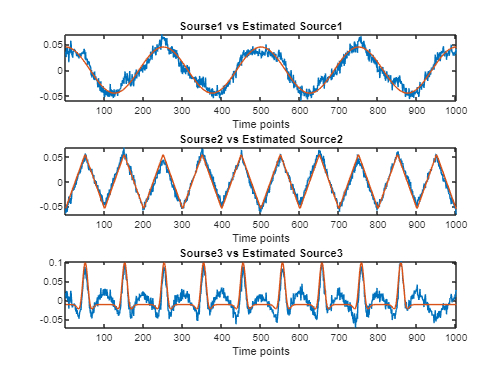

figure
subplot(3,1,1)
plot(time_points,S_hat4(1,:),time_points,S(1,:))
xlim([1,1001])
title('Sourse1 vs Estimated Source1')
xlabel('Time points')

subplot(3,1,2)
plot(time_points,S_hat4(2,:),time_points,S(2,:))
xlim([1,1001])
title('Sourse2 vs Estimated Source2')
xlabel('Time points')

subplot(3,1,3)
plot(time_points,-S_hat4(3,:),time_points,S(3,:))
xlim([1,1001])
title('Sourse3 vs Estimated Source3')
xlabel('Time points')

S_hat4 = [S_hat4(1,:);S_hat4(2,:);-S_hat4(3,:)]; 
Errr = (norm(S_hat4 - S,"fro")/norm(S,"fro"))^2

Errr = 0.1776

**The error of the final result is shown above.**

## Conclusion

As it is shown above the methods have results as below:

**Kurt Maximization (GP)** : *0.360 second --> error = 0.312*

**Kurt Maximization (Fixed-Point)** :* 0.390 second --> error = 0.312*

**Handle the Outlier Data (GP)** : *0.55 second --> error = 0.312*

**Handling Outlier Data (Fixed-Point)** : *0.60 second --> error = 0.17 *

These results show us that of **time** is our constraint then **Kurt Maximization (GP)** is the better choise but if we need the most **accuracy** then **Handling Outlier Data (Fixed-Point)** is the better choise.

It should be mentioned that overally, **Kurt Maximization (GP)** and **Kurt Maximization (Fixed-Point)** have **same time-consuming**.

## Functions.

### Gradient Projection

function [B, e] = g_projection(X,init_B,mu,iters,err)
    B = init_B;
    e = zeros(1,iters);
    for iter = 1:iters
        Y = B*X;
        Psi = score_function_estimator(Y);
        G = Ex1(Psi,X')-pinv(B).';
        Bp = B;
        B = B-mu*G;
        B = normr(B);
        e(iter) =  norm(B-Bp);
        if e(iter) < err
            e = e(1:iter);
            break;
        end
    end
end

### Score Function Estimator

function Psi = score_function_estimator(Y)
    Psi = zeros(size(Y,1),size(Y,2));
    for i = 1:size(Y,1)
        
        ym1 = Y(i,:);
        ym2 = ym1.*2;
        ym3 = ym1.*3;
        ym4 = ym1.*4;
        ym5 = ym1.*5;
        ym0 = ones(1,length(ym1));
        
        Ky = [ym0;ym1;ym2;ym3;ym4;ym5];
        dKy = [zeros(1,length(ym0));ym0;2*ym1;3*ym2;4*ym3;5*ym4];
        theta = pinv(Ex1(Ky,Ky'))*E_(dKy);
        psi = theta'*Ky;
        Psi(i,:) = psi;
    end
end

### Deflation Gradient Projection

function [B, e] = deflation_g_projection(Z,init_B,mu,iters,err)
    B = init_B;
    e = zeros(1,iters);
    for iter = 1:iters
        Bp = B;
        for i = 1:size(B,1)
            Y = B*Z;
            b = B(i,:);
            Psi = score_function_estimator(Y(i,:));
            g = Ex1(Psi,Z');
            b = b-mu*g;
            if i ~= 0
                b = ((eye(size(B))-transpose(B(1:i-1,:))*B(1:i-1,:))*b').';
            end
            b = normr(b);
            B(i,:) = b;
        end
        e(iter) = norm(B-Bp);
        if e(iter) < err
            e = e(1:iter);
            break;
        end
    end
end

### Equivarient Gradient Projection

function [B, e] = equivarient_g_projection(X,init_B,mu,iters,err)
    B = init_B;
    e = zeros(1,iters);
    for iter = 1:iters
        Y = B*X;
        Psi = score_function_estimator(Y);
        f = zeros(size(B));
        for i = 1:size(B,1)
            for j = 1:size(B,2)
                if j ~= i
                    f(i,j) = Ex1(Psi(i,:),transpose(Y(j,:)));
                end
            end
        end
        
        Bp = B;
        B = (eye(size(B))-mu*f)*B;
        B = normr(B);
        e(iter) = norm(B-Bp);
        if e(iter) < err
            e = e(1:iter);
            break;
        end
    end
end

### Making Non-Gaussian Observations

function B = Non_Gaussianing(Z,init_B,mu,iters,err,approach,outlier)
    B = init_B;
    for i = 1:size(B,1)
        init_b = B(i,:);
        [b,f,e] = kurt_maximizer(Z,B,init_b,mu,iters,err,i,approach,outlier);
        B(i,:) = b;
        
        if length(f) > 1 && outlier == 0
            fprintf('Row %d of B',i)
            figure
            subplot(1,2,1)
            plot(f)
            xlabel('Iteration')
            ylabel('|kurt(y)|')
            title('Objective Function')
            
            subplot(1,2,2)
            plot(e)
            xlabel('Iteration')
            ylabel('Error')
            xlim([1 100])
            title('Cost Function')
        end
    end
end


### Kurt Maximizer

function [b,f,e] = kurt_maximizer(Z,B,init_b,mu,iters,err,i,approach,handle_outlier)
    b = init_b;
    y = b*Z;
    e = zeros(1,iters);
    f = zeros(1,iters);
    for iter = 1:iters
        %Using kurt function
        if handle_outlier == 0
            f(iter) = abs(kurtosis(y));
        %Not using kurt function
        elseif handle_outlier == 1
            f1 = Ex2(ones(size(y)),-exp(-(y.^2)/2))+1/sqrt(2);
            f(iter) = f1^2;
        end
        
        %Gradient Projection
        if approach == 'GP'
            if handle_outlier == 0
                g = transpose(sign(kurtosis(y))*(Ex2(Z,y.^3)-3*b'));
            elseif handle_outlier == 1
                g = transpose(f1*Ex2(Z,y.*exp(-y.^2/2)));
            end
            b = b+mu*g;
        %Fixed point 
        elseif approach == 'FP'
            if handle_outlier == 0
                b = transpose(Ex2(Z,y.^3)-3*b');
            elseif handle_outlier == 1
                b = transpose(Ex2(Z,y.*exp(-(y.^2)/2)));
            end
        end
        
        %projection
        if i ~= 1
            b = transpose((eye(size(B))-transpose(B(1:i-1,:))*B(1:i-1,:))*b');
        end
        b = b/norm(b);
        
        yp = y;
        y = b*Z;
        if handle_outlier == 0
            e(iter) = abs(kurtosis(y))-abs(kurtosis(yp));
            if e(iter) < err
                e = e(1:iter);
                f = f(1:iter);
                break;
            end
        end
    end
end


### Other Functions (Expectation and Initializing Seperation Matrix)

function e = Ex2(Z,Y)
    S = zeros(size(Z));
    for t = 1:size(Y,2)
        S(:,t) = Z(:,t).*Y(:,t);
    end
    e = sum(S,2)/size(Y,2);
end

function e = Ex1(X,Y)
    e = zeros(size(X,1),size(Y,2));
    for i = 1:size(X,2)
        e = e+X(:,i)*Y(i,:);
    end
    e = e./size(X,2);
end

function e = E_(X)
    e = sum(X,2)/size(X,2);
end

function [Z,W] = whiten(X)
R_X = X*X';
[U,D] = eig(R_X);
[d,ind] = sort(diag(D),'descend');
Ds = D(ind,ind);
Us = U(:,ind);
for i = 1:length(Ds)
    D(i,i) = Ds(i,i).^(-0.5);
end
W = D*Us';
Z = W*X;
end
